% Plot graphs
Plot = false;
% Save praphs
Save_graph = true;

% Determine where your m-file's folder is
folder = fileparts(which("opt_problem.mlx"));
% Add that folder plus all subfolders to the path
addpath(genpath(folder));

#### GFDM parameters.

gfdm = struct;
%gfdm.K = 5; % Subcarriers
%gfdm.M = 4; % Subsymbols
gfdm.K = K;
gfdm.M = M;

gfdm.CP = 0; % CP length

SEM = "802.11ac";
Channel = 20; % Channel bandwidth (MHz)

uti_threshold =  0.55; % Utilize rate threshold

gfdm = GFDM_init(gfdm);

D = gfdm.D;

Normalized frequency $fT_s = \frac{f}{f_s}$ and normalized frequency interval $\Delta fT_s
$

delta_fTs = 0.01;
fTs_limit = 0.5;   % rc filter limit

% f_range_end should be divisible by delta_f
if mod(fTs_limit,fTs_limit)
    msg = 'normalized frequency sampling interval delta_fTs can not equally spaces fTs_range';
    error(msg);
end

fTs_range = [0 fTs_limit];
fTs = -fTs_range(2):delta_fTs:fTs_range(2);

Interpolation filter $P(f)$

P = rc_filter(delta_fTs, fTs_range, 0.1);

All combinations of $K_{\textrm{on}}$ and $M_{\textrm{on}}$ with decreasing order: $N$

The number of element used $N_{\textrm{sort}} \left(n\right)$ is the result of using $K_{\textrm{on}}$ = $\textrm{sort}\_\textrm{idx}\_K\left(n\right)$ and $M_{\textrm{on}}$ = $\textrm{sort}\_\textrm{idx}\_M\left(n\right)$.

[N_sort, sort_idx_K, sort_idx_M] = sort_N(gfdm);

#### Find the maximum used resource $N$ and its corresponding $K_{\textrm{on}}$ and $M_{\textrm{on}}$.

% Start from the first index with utilize rate grater than the utilize rate
% threshold
uti_rate = N_sort/gfdm.D;
idx_start = find(uti_rate < uti_threshold, 1) - 1;

if idx_start < 2
    idx_start = 2;
end

feasible_count = 0; % Feasible set counter
K_on_set = zeros(1, 5);
M_on_set = zeros(1, 5);

% Loop used resources
N_counter = idx_start;
N_start = tic;

for n = idx_start:D
    % How many sets remain with the same utilize rate as the current one
    tie = numel(find(N_sort(N_counter:end) == N_sort(N_counter)));

    KonMon = N_sort(n);
    gfdm.K_on = sort_idx_K(n); gfdm.M_on = sort_idx_M(n);
    fprintf("%d. K_on = %d M_on = %d N = %d \n", N_counter-idx_start+1, gfdm.K_on, gfdm.M_on, KonMon);
    fprintf("Utilize rate: %f \n", KonMon/D);

    S = Dottorro(gfdm, Channel, Channel, P, SEM, fTs);

    % Feasible set found
    if ~isnan(S)
        feasible_count = feasible_count + 1;
        K_on_set(feasible_count) = gfdm.K_on;
        M_on_set(feasible_count) = gfdm.M_on;
    end

    % Break if there is no remaining set with the same utilize rate as the
    % feasible one
    if feasible_count~=0 && tie==1
        break;
    end

    N_counter = N_counter + 1;
end

K_on_set = K_on_set(1:feasible_count);
M_on_set = M_on_set(1:feasible_count);

fprintf('===============================\n');
fprintf("K_on = %s M_on = %s N = %d \n", join(string(K_on_set), ','), join(string(M_on_set), ','), KonMon);
fprintf("Utilized rate: %f \n", KonMon/D);
fprintf('Max utilization time: %s\n', duration([0, 0, toc(N_start)]));
fprintf('===============================\n');

#### Bisection method to find the max sampling frequency $f_s$.

fs = zeros(size(K_on_set));
S_solved = zeros([gfdm.D, gfdm.D, numel(K_on_set)]);

for idx = 1:numel(K_on_set)
    gfdm.K_on = K_on_set(idx);
    gfdm.M_on = M_on_set(idx);

    % Bisection stop criteria
    fs_low = Channel;
    fs(idx) = fs_low;
    fs_up = 2*fs_low;
    fs_criteria = 0.1;
    fs_diff = fs_criteria;
    fs_mid = fs_up;

    while fs_diff >= fs_criteria

#### Dottorro iterative algorithm & optimization problem


$$\mathbf{S}=\mathbf{g}\mathbf{g}^H$$


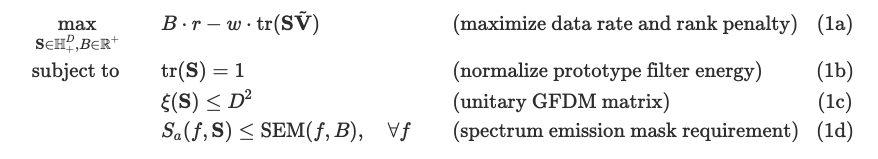

        S = Dottorro(gfdm, fs_mid, Channel, P, SEM, fTs);

        if isnan(S)
            % Bisection update if infeasible
            fs_up = fs_mid;
        else
            S_solved(:, :, idx) = S;

            % Bisection update if feasible
            fs_low = fs_mid;
            fs(idx) = fs_mid;

            if Plot == 1
                switch SEM
                    case "802.11ac"
                        mask_dB = SEM_ac(fTs, fs(idx), Channel);
                    case "802.11b"
                        mask_dB = SEM_b(fTs, fs(idx), Channel);
                end
                mask_linear = db2pow(mask_dB);
                S_a_S = PSD_S(gfdm, S, fs(idx), zeros(size(P)), fTs, P);
                plot_PSD(gfdm, S_a_S, mask_dB, fTs, fs(idx));
            end

        end

        fs_diff = fs_up - fs_low;
        % Midpoint
        fs_mid = (fs_up + fs_low)/2;
    end
end

fprintf("K: %d M: %d fs: %s \n",gfdm.K, gfdm.M, join(string(fs), ','));
[max_fs, idx] = max(fs);
gfdm.K_on = K_on_set(idx);
gfdm.M_on = M_on_set(idx);

g = S2g(S_solved(:, :, idx));
effective_data_rate = (KonMon/(D+gfdm.CP)) * max_fs;

switch SEM
    case "802.11ac"
        mask_dB = SEM_ac(fTs, max_fs, Channel);
    case "802.11b"
        mask_dB = SEM_b(fTs, max_fs, Channel);
end
mask_linear = db2pow(mask_dB);
P = rc_filter(delta_fTs, fTs_range, 0.1);
psd_temp = zeros(size(P));
% g = S2g(S); G = g2chaG(g, gfdm.K, gfdm.M);
% S_a = PSD_G(gfdm, G, f_range, delta_f);
S_a_S = PSD_S(gfdm, S_solved(:, :, idx), max_fs, psd_temp, fTs, P);

if Save_graph
    save_PSD(gfdm, S_a_S, mask_dB, fTs, max_fs, effective_data_rate);
end

if Plot
     
    plot_PSD(gfdm, S_a_S, mask_dB, fTs, max_fs, effective_data_rate);
end

% to open the figure
% openfig('newout.fig','new','visible')